folder = "DB1"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  %subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  %imshow(Im{i}) %%Show the current image in a subplot.
end

Convert to YCbCr and create an eye map according to the *Face Detection in Color Images* paper.

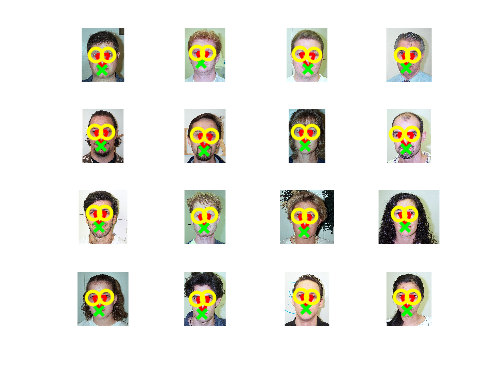

%The following requires image processing toolbox.
tic
figure;
for i = 1:length(Im)
    subplot(4,4, i); %%define location to plot the image in our subplot.
    currentImage = Im{i};
    currentImage = lighting_compensation(currentImage,0.20);
    
    EyeMap = eye_detection(currentImage);
    size_img = size(currentImage);
    %EyeMap = bwpropfilt(EyeMap, 'Perimeter', 7);
    MouthMap = mouth_detection(currentImage);
    
    [lEye_c, rEye_c, mouth_c, e_regions,m_regions ] = face_triangle_coordinates(MouthMap, EyeMap);
    
    imshow(currentImage)
    hold on
%     plot([1,size_img(2)],[3/5*size_img(1),3/5*size_img(1)],'Color','b','LineWidth',2)
%     plot([1,size_img(2)],[2/5*size_img(1),2/5*size_img(1)],'Color','b','LineWidth',2)
%     plot([1,size_img(2)],[3.9/5*size_img(1),3.9/5*size_img(1)],'Color','b','LineWidth',2)
    plot([lEye_c(1),rEye_c(1)],[lEye_c(2),rEye_c(2)],'Color','r','LineWidth',2)
    plot([mouth_c(1),rEye_c(1)],[mouth_c(2),rEye_c(2)],'Color','r','LineWidth',2)
    plot([mouth_c(1),lEye_c(1)],[mouth_c(2),lEye_c(2)],'Color','r','LineWidth',2)
    for idx = 1:length(m_regions)
        plot(m_regions(idx).Centroid(1),m_regions(idx).Centroid(2), 'x', 'markersize', 8, "LineWidth",2, 'Color', 'green')
    
    end
    for idx = 1:length(e_regions)
        plot(e_regions(idx).Centroid(1),e_regions(idx).Centroid(2), 'o', 'markersize', 8, "LineWidth",2, 'Color', 'yellow')
    
    end
    hold off
end 

toc

Elapsed time is 11.548706 seconds.


tic
allFaces = cell(1,nfiles); %%Allocate space

for j = 1:length(Im)
    currentImage = Im{j};
    currentImage = lighting_compensation(currentImage,0.20);
    EyeMap = eye_detection(currentImage);
    MouthMap = mouth_detection(currentImage);
    
    [lEye_c, rEye_c, mouth_c, e_regions,m_regions ] = face_triangle_coordinates(MouthMap, EyeMap);
    [rotated_image, lEye_rotated, rEye_rotated, mouth_rotated] = rotate_image(currentImage, lEye_c, rEye_c, mouth_c);
    
%     figure;
%     subplot(1,2,1);
%     imshow(rotated_image);
%     hold on
%     plot([lEye_rotated(1),rEye_rotated(1)],[lEye_rotated(2),rEye_rotated(2)],'Color','r','LineWidth',2)
%     plot([mouth_rotated(1),rEye_rotated(1)],[mouth_rotated(2),rEye_rotated(2)],'Color','r','LineWidth',2)
%     plot([mouth_rotated(1),lEye_rotated(1)],[mouth_rotated(2),lEye_rotated(2)],'Color','r','LineWidth',2)
%     hold off
    
    cropped_image = crop_face(rotated_image, lEye_rotated, rEye_rotated);
%    subplot(1,2,2);
%    imshow(cropped_image);
    allFaces{j} = cropped_image;
end

toc

Elapsed time is 16.425928 seconds.


Calculate eigenfaces.

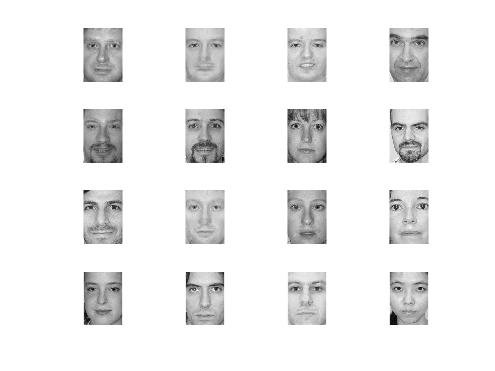

[linearCombination, weight, averageFace, u, index]= compute_eigenFace(allFaces);
figure;
for i = 1:16
    subplot(4,4,i);
    imshow(linearCombination{i});
end

Check if image is in database. Should be moved to a function

ans = 0

ans = 24.2428

ans = 35.9749

ans = 31.0226

ans = 28.5920

ans = 31.9813

ans = 31.4119

ans = 42.7515

ans = 27.1393

ans = 29.2702

ans = 19.3833

ans = 38.2832

ans = 23.1637

ans = 26.9753

ans = 38.1001

ans = 33.1455

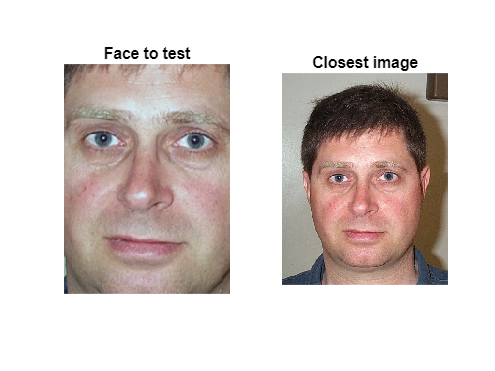

ans = 24.2428

ans = 0

ans = 14.3248

ans = 29.9046

ans = 43.2867

ans = 39.5231

ans = 43.7005

ans = 37.2332

ans = 25.0032

ans = 12.1121

ans = 27.2880

ans = 29.0032

ans = 31.9478

ans = 27.4674

ans = 20.5327

ans = 31.5172

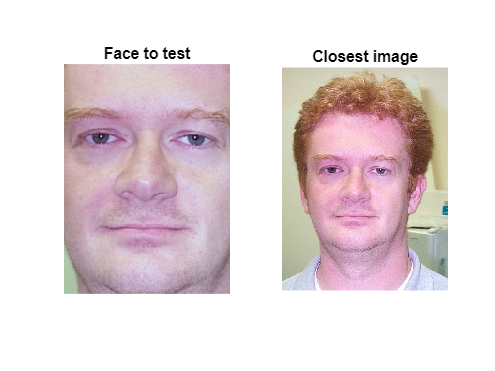

ans = 35.9749

ans = 14.3248

ans = 0

ans = 35.6681

ans = 50.7715

ans = 45.8338

ans = 51.6626

ans = 36.8596

ans = 29.3271

ans = 15.1551

ans = 34.3668

ans = 29.4741

ans = 41.9085

ans = 31.5570

ans = 21.6651

ans = 35.9453

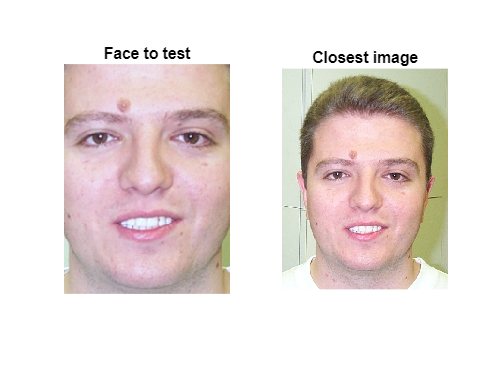

ans = 31.0226

ans = 29.9046

ans = 35.6681

ans = 0

ans = 35.2194

ans = 35.3787

ans = 40.9005

ans = 42.4558

ans = 33.7653

ans = 33.8408

ans = 27.9741

ans = 40.0250

ans = 34.3260

ans = 34.5803

ans = 38.6287

ans = 37.6077

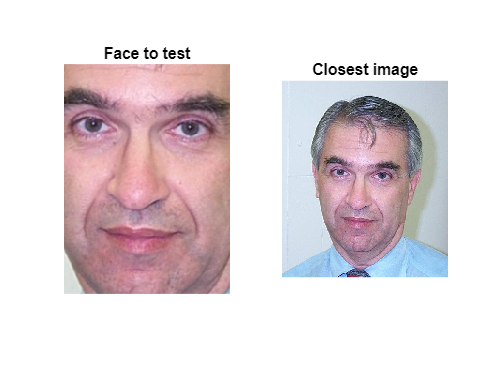

ans = 28.5920

ans = 43.2867

ans = 50.7715

ans = 35.2194

ans = 0

ans = 22.8647

ans = 36.6642

ans = 51.7835

ans = 39.6562

ans = 48.6205

ans = 28.3513

ans = 56.1190

ans = 32.0049

ans = 44.6494

ans = 57.0313

ans = 46.7432

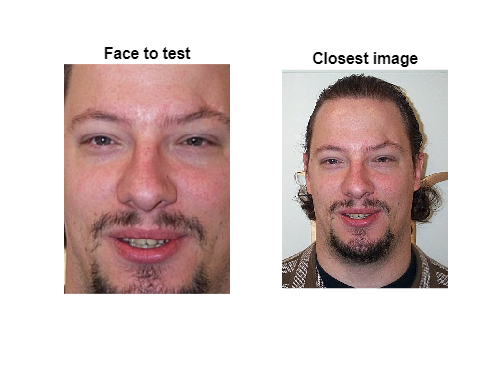

ans = 31.9813

ans = 39.5231

ans = 45.8338

ans = 35.3787

ans = 22.8647

ans = 0

ans = 40.1986

ans = 47.7767

ans = 37.1854

ans = 43.7584

ans = 31.7296

ans = 52.8829

ans = 37.0559

ans = 42.3980

ans = 48.6701

ans = 44.1475

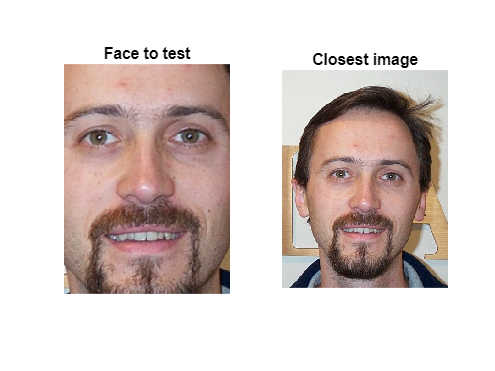

ans = 31.4119

ans = 43.7005

ans = 51.6626

ans = 40.9005

ans = 36.6642

ans = 40.1986

ans = 0

ans = 59.1354

ans = 44.2329

ans = 48.5581

ans = 31.1752

ans = 52.9770

ans = 31.3370

ans = 42.4135

ans = 55.0845

ans = 45.5287

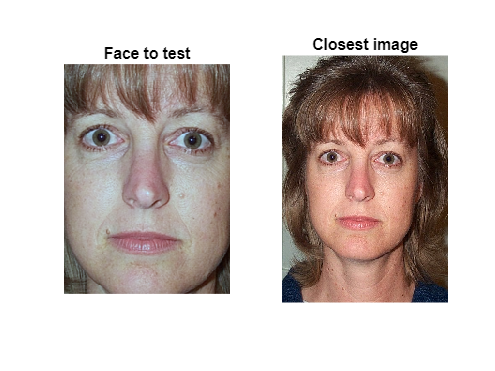

ans = 42.7515

ans = 37.2332

ans = 36.8596

ans = 42.4558

ans = 51.7835

ans = 47.7767

ans = 59.1354

ans = 0

ans = 40.9219

ans = 38.9563

ans = 41.5987

ans = 42.5223

ans = 52.2024

ans = 42.6972

ans = 39.5843

ans = 49.8658

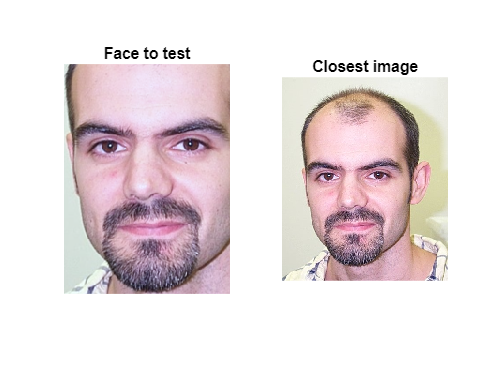

ans = 27.1393

ans = 25.0032

ans = 29.3271

ans = 33.7653

ans = 39.6562

ans = 37.1854

ans = 44.2329

ans = 40.9219

ans = 0

ans = 29.9676

ans = 30.0021

ans = 36.0964

ans = 34.7632

ans = 26.0367

ans = 31.2245

ans = 35.9057

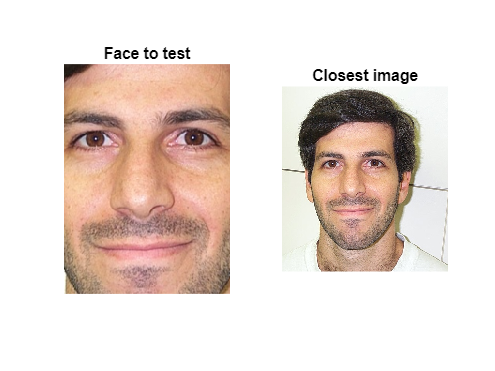

ans = 29.2702

ans = 12.1121

ans = 15.1551

ans = 33.8408

ans = 48.6205

ans = 43.7584

ans = 48.5581

ans = 38.9563

ans = 29.9676

ans = 0

ans = 30.1138

ans = 26.1880

ans = 40.6470

ans = 30.8816

ans = 17.4830

ans = 32.1147

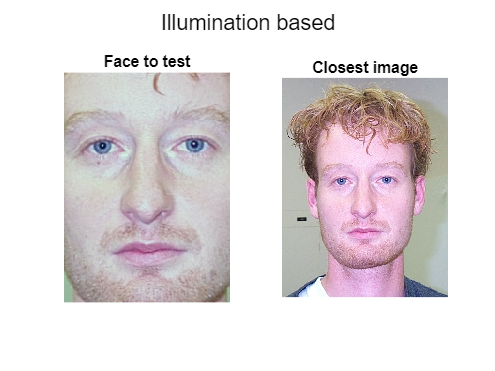

ans = 19.3833

ans = 27.2880

ans = 34.3668

ans = 27.9741

ans = 28.3513

ans = 31.7296

ans = 31.1752

ans = 41.5987

ans = 30.0021

ans = 30.1138

ans = 0

ans = 37.9818

ans = 27.3040

ans = 28.9577

ans = 36.6761

ans = 35.4673

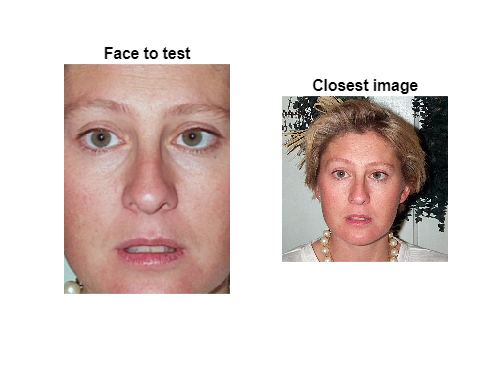

ans = 38.2832

ans = 29.0032

ans = 29.4741

ans = 40.0250

ans = 56.1190

ans = 52.8829

ans = 52.9770

ans = 42.5223

ans = 36.0964

ans = 26.1880

ans = 37.9818

ans = 0

ans = 44.7621

ans = 34.9869

ans = 26.9756

ans = 37.4216

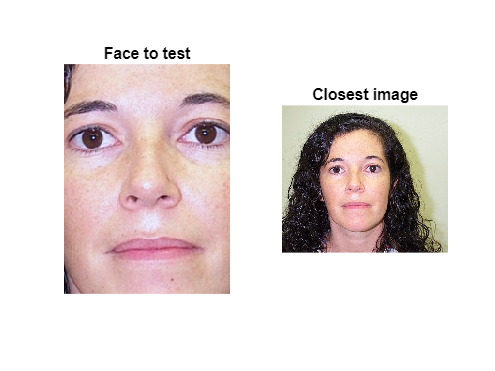

ans = 23.1637

ans = 31.9478

ans = 41.9085

ans = 34.3260

ans = 32.0049

ans = 37.0559

ans = 31.3370

ans = 52.2024

ans = 34.7632

ans = 40.6470

ans = 27.3040

ans = 44.7621

ans = 0

ans = 33.6105

ans = 45.9623

ans = 32.1731

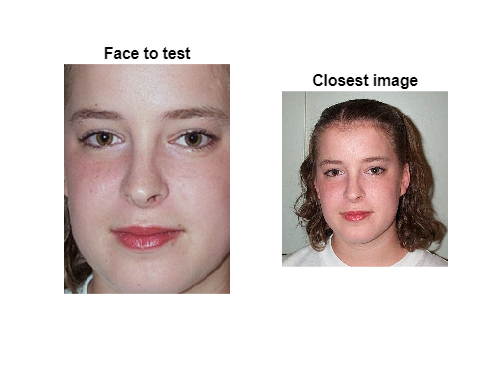

ans = 26.9753

ans = 27.4674

ans = 31.5570

ans = 34.5803

ans = 44.6494

ans = 42.3980

ans = 42.4135

ans = 42.6972

ans = 26.0367

ans = 30.8816

ans = 28.9577

ans = 34.9869

ans = 33.6105

ans = 0

ans = 35.6357

ans = 33.6648

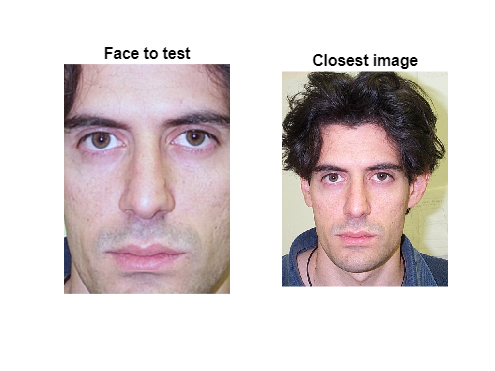

ans = 38.1001

ans = 20.5327

ans = 21.6651

ans = 38.6287

ans = 57.0313

ans = 48.6701

ans = 55.0845

ans = 39.5843

ans = 31.2245

ans = 17.4830

ans = 36.6761

ans = 26.9756

ans = 45.9623

ans = 35.6357

ans = 0

ans = 37.7573

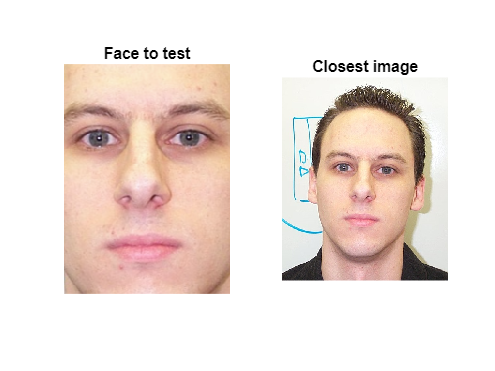

ans = 33.1455

ans = 31.5172

ans = 35.9453

ans = 37.6077

ans = 46.7432

ans = 44.1475

ans = 45.5287

ans = 49.8658

ans = 35.9057

ans = 32.1147

ans = 35.4673

ans = 37.4216

ans = 32.1731

ans = 33.6648

ans = 37.7573

ans = 0

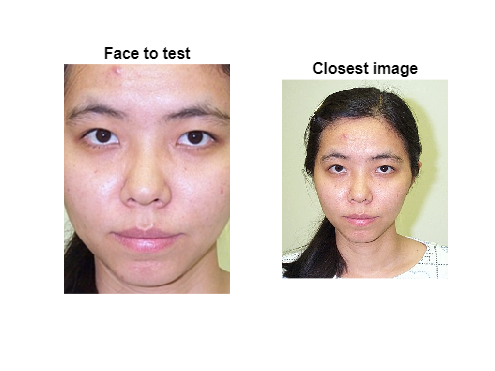

for k = 1:16
    testFace = allFaces{k};
    figure;
    subplot(1,2,1);
    imshow(testFace);
    title('Face to test');
    
    %%Reshape the test image and subtract the average face.
    testFace = rgb2gray(testFace);
    testFace = reshape(testFace,[],1);
    phi = testFace - averageFace;
    
    %%Calculate weights
    weight2 = zeros(1,12);
    for j = 1:12
        weight2(1,j) = u(:,index(j))'* phi;
    end
    
    error = 10000; %%minimum error
    index2 = 0;
    
    for i = 1:16
        sqrt(sum((weight2 - weight(i,:)).^2))
        if sqrt(sum((weight2 - weight(i,:)).^2)) < error
            error = sqrt(sum((weight2 - weight(i,:)).^2)); %%update minimum error
            index2 = i; %%update index.
        end
    end
    subplot(1,2,2);
    imshow(Im{index2});
    title('Closest image');
end

folder = "DB3"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  %subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  %imshow(Im{i}) %%Show the current image in a subplot.
end
tic
allFaces = cell(1,nfiles); %%Allocate space
for j = 1:length(Im)
    currentImage = Im{j};
    currentImage = lighting_compensation(currentImage,0.20);
    EyeMap = eye_detection(currentImage);
    MouthMap = mouth_detection(currentImage);
    
    [lEye_c, rEye_c, mouth_c, e_regions,m_regions ] = face_triangle_coordinates(MouthMap, EyeMap);
    [rotated_image, lEye_rotated, rEye_rotated, mouth_rotated] = rotate_image(currentImage, lEye_c, rEye_c, mouth_c);
    
%     figure;
%     subplot(1,2,1);
%     imshow(rotated_image);
%     hold on
%     plot([lEye_rotated(1),rEye_rotated(1)],[lEye_rotated(2),rEye_rotated(2)],'Color','r','LineWidth',2)
%     plot([mouth_rotated(1),rEye_rotated(1)],[mouth_rotated(2),rEye_rotated(2)],'Color','r','LineWidth',2)
%     plot([mouth_rotated(1),lEye_rotated(1)],[mouth_rotated(2),lEye_rotated(2)],'Color','r','LineWidth',2)
%     hold off
    
    cropped_image = crop_face(rotated_image, lEye_rotated, rEye_rotated);
%    subplot(1,2,2);
%    imshow(cropped_image);
    allFaces{j} = cropped_image;
end

toc

Elapsed time is 29.323492 seconds.


[F, u, weight] = fisherfaces(imagefiles, allFaces);
c = 8;
N = size(allFaces{1});
figure;
weight

weight =  -217.3610   10.7965   77.7267    6.6160   18.3257   80.9584   -2.5784   18.2252
   12.2781    9.9993  106.4624    1.1057   55.6000  -66.3775 -269.0581  -85.3373
    6.9322  -15.1187  -37.7520   90.4206  -21.4723   53.5165  -91.3128   -2.4484
    5.3826   62.0669  -32.6665  -18.5534   29.9792   43.4431    7.1185  -51.0201
   -5.3855   15.1562    3.1007   40.8319   15.3512  -23.3094   48.3520  -12.9079
    2.8462  -26.0244    4.0464   -2.4211    9.1250    9.5441   15.9812  -17.2183
   -1.1325   -0.7691    1.5094   -1.9483   -8.5132   -0.9542    0.5168   -5.2529


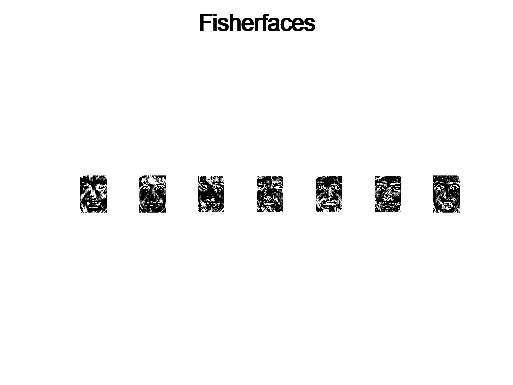

for i = 1 : c-1
    F_temp = reshape(F(:,i), N(1), N(2));
    subplot(1,7,i);
    F_temp = normalize(F_temp);
    imshow(F_temp);
end
sgtitle('Fisherfaces')


answers = zeros(1,length(allFaces));
for i = 1:length(allFaces)
    TestPerson = allFaces{i};
    TestPerson = rgb2gray(TestPerson);
    TestPerson = reshape(TestPerson,[],1);
    weightTestPerson = F'*TestPerson;
    error = 10000; %%minimum error
    index2 = 0;
    for j = 1:c
        sqrt(sum((weightTestPerson - weight(:,j)).^2));
        if sqrt(sum((weightTestPerson - weight(:,j)).^2)) < error
            error = sqrt(sum((weightTestPerson - weight(:,j)).^2)); %%update minimum error
            index2 = j; %%update index.
        end
    end
    answers(1,i) = index2;
end
%%Not sure if "expected" is correct.
expected = [1 2 3 4 5 2 3 6 4 5 1 2 7 8 3 6 4 5 1 8 6 8]

expected =      1     2     3     4     5     2     3     6     4     5     1     2     7     8     3     6     4     5     1     8     6     8


answers

answers =      1     6     5     4     4     2     3     6     8     2     1     8     7     8     3     6     4     5     1     6     6     2


Result = answers == expected

Result = 1×22 logical array
   1   0   0   1   0   1   1   1   0   0   1   0   1   1   1   1   1   1   1   0   1   0



%%Display number of correct/wrong detections. 0 = wrong. 1 = correct
x = unique(Result);
N = numel(x);
count = zeros(N,1);
for k = 1:N
    count(k) = sum(Result==x(k));
end
disp([ x(:) count ]);

     0     8
     1    14



% 
% figure;
% for i = 1 : c
%     subplot(1,7,i);
%     eigenface = reshape(u(:,i), N(1), N(2));
%     eigenface = normalize(eigenface);
%     imshow(eigenface)
% end
% sgtitle('Eigenfaces')